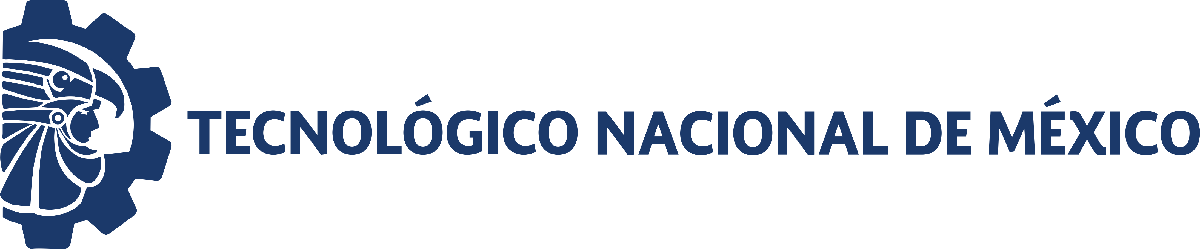                                 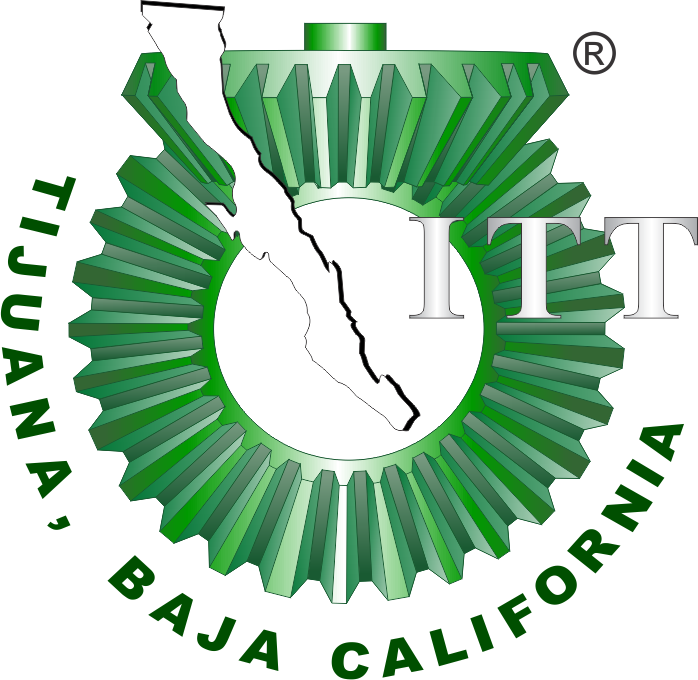

#                                              Proyecto Final : Retinosis en los fotorreceptores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

                                                                                                                                                                                           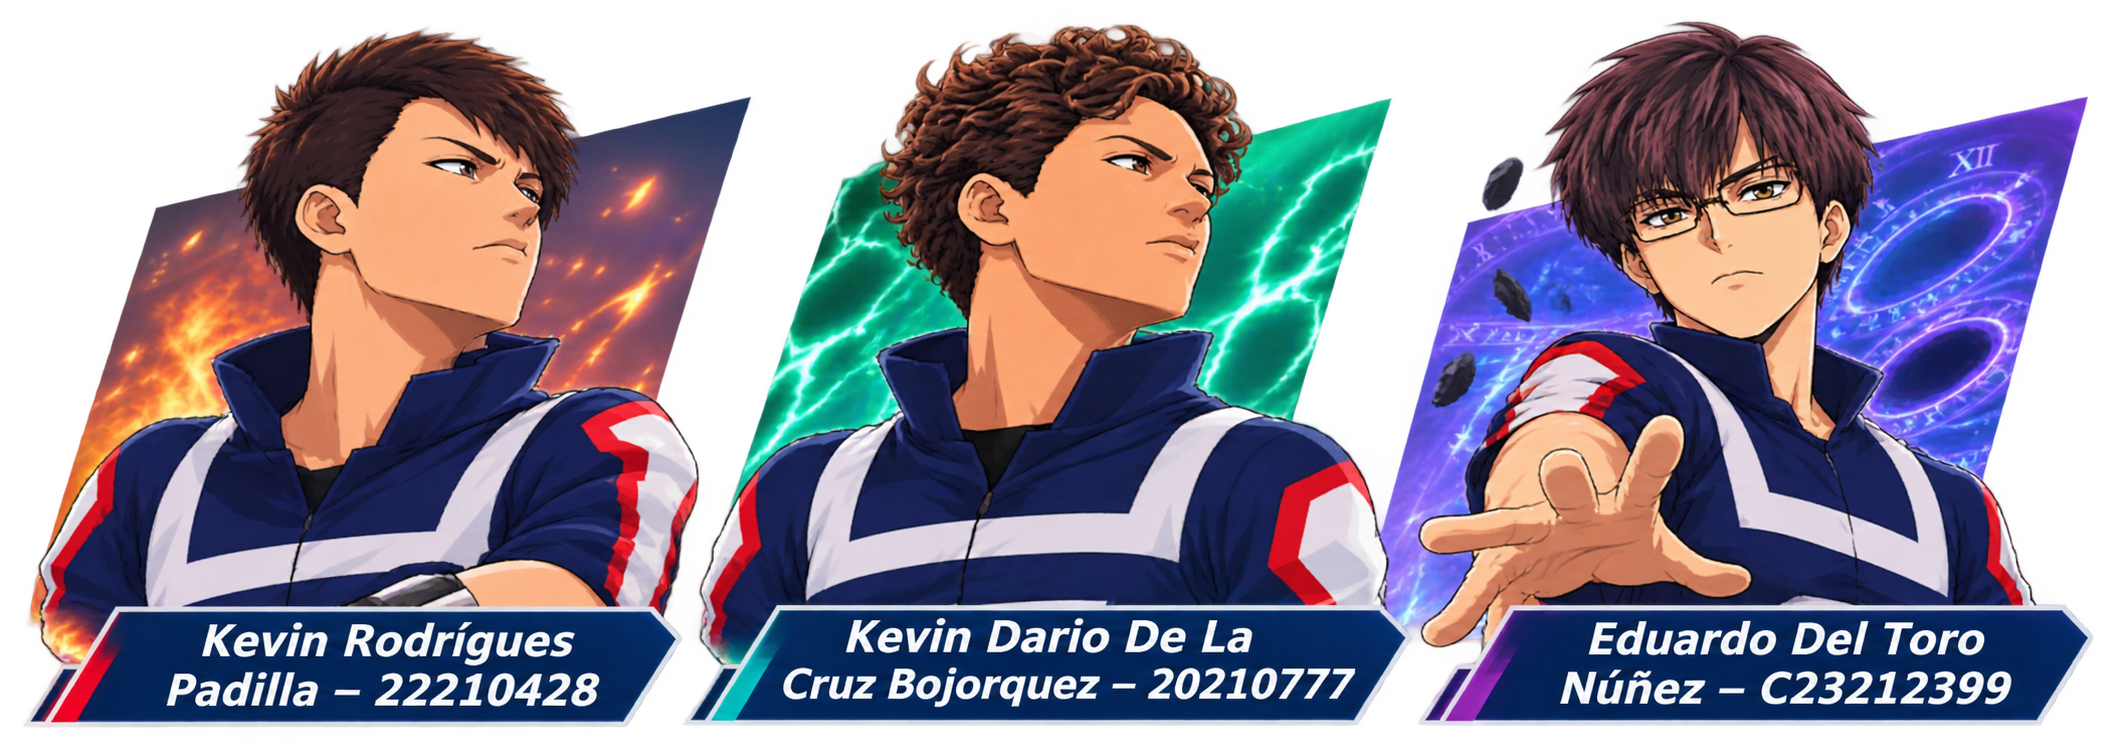                                                                                                                                  

Correos institucionales: ** L22210428@TIJUANA.TECNM.MX , L20210777@TIJUANA.TECNM.MX , LC23212399@TIJUANA.TECNM.MX**

Asignatura:   Modelado de Sistemas Fisiológicos

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('ProyectoFinal.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('ProyectoFinal.slx', parameters);
datos = table(x.tout(:),x.F(:),x.Fs1(:),x.FsC(:),x.PID(:), ...
'VariableNames',{'t','F','Fs1','FsC','PID'});
writetable(datos,'C:\Users\kevin\Desktop\ProyectoFinal.csv');

## **Respuesta al impulso: Control y caso**

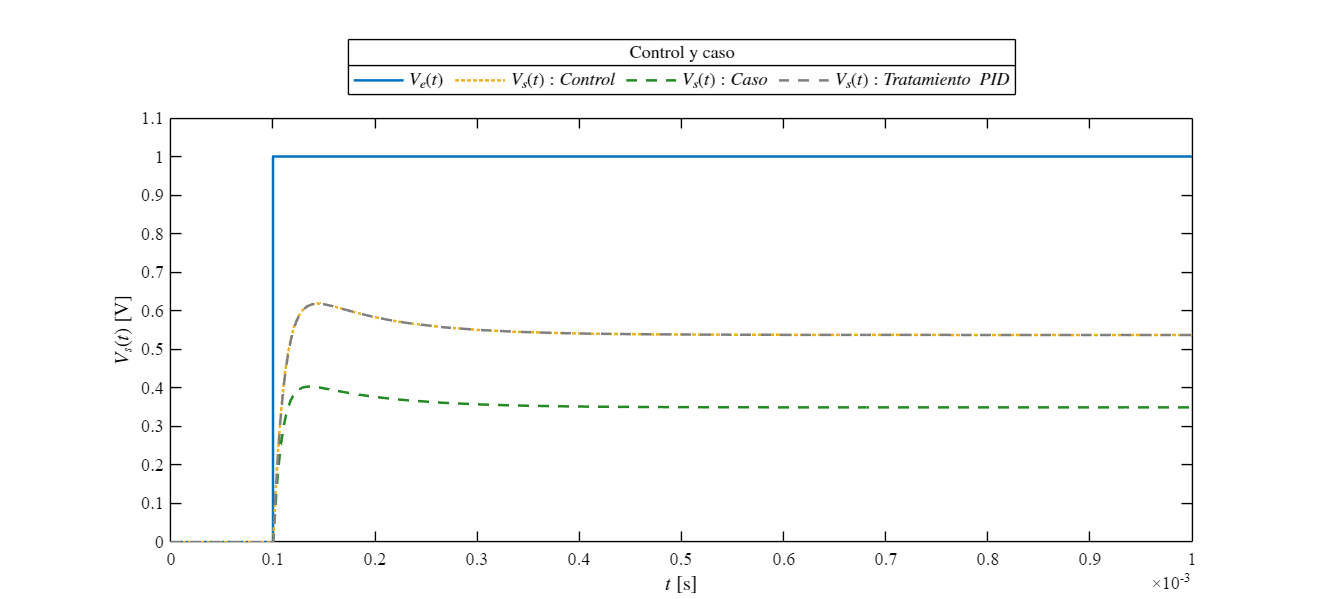

plotsignals(x.tout,x.F,x.Fs1,x.FsC,x.PID)

function plotsignals(t,c,c1,c2,c3)

fig = figure('Color','w');
set(fig,'Units','inches','Position',[1,1,11,5], ...
    'InvertHardcopy','off');

ax = axes('Parent',fig);

set(ax,'FontName','Times New Roman', ...
    'FontSize',11, ...
    'Color','w', ...
    'XColor','k', ...
    'YColor','k', ...
    'GridColor','k', ...
    'Box','on');

hold(ax,'on');
grid(ax,'off');

clr1 = [0,114,189]/255;
clr2 = [237,177,32]/255;
clr3 = [34,139,34]/255;
clr4 = [128,128,128]/255;

order = [clr1;clr2;clr3;clr4];
colororder(ax,order)

plot(ax,t,c,'-', ...
    t,c1,':', ...
    t,c2,'--', ...
    t,c3,'--', ...
    'LineWidth',1.5, ...
    'MarkerSize',5, ...
    'MarkerIndices',1:1e3:length(t));

L = legend(ax,'$V_e(t)$', ...
    '$V_s(t): Control$', ...
    '$V_s(t): Caso$', ...
    '$V_s(t): Tratamiento\ PID$');

set(L,'Interpreter','latex', ...
    'Location','northoutside', ...
    'Orientation','horizontal', ...
    'Color','w', ...
    'TextColor','k', ...
    'EdgeColor','k', ...
    'FontSize',11);

title(L,'Control y caso','Color','k')

xlabel(ax,'$t$ [s]', ...
    'Interpreter','latex','Color','k')

ylabel(ax,'$V_s(t)$ [V]', ...
    'Interpreter','latex','Color','k')

xlim(ax,[0 1e-3]);
xticks(ax,0:1e-4:1e-3)

ylim(ax,[0 1.1]);
yticks(ax,0:0.1:1.1)

exportgraphics(fig,'Control_caso_matlab.pdf', ...
    'ContentType','vector', ...
    'BackgroundColor','white')

end


